106010006 黃詩瑜 電機21 HW4

1.

(a)


$$x\left\lbrack n\right\rbrack =n{\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack ,$$


帶入DTFT公式


$$\begin{array}{l}
\tilde{X} \left(e^{j\Omega } \right)=\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack e^{-j\Omega n} =\sum_{n=0}^{\infty } n{\left(0\ldotp 9\right)}^n e^{-j\Omega n} \\
\tilde{X} \left(Z\right)=\frac{0\ldotp 9Z^{-1} }{{\left(1-0\ldotp 9Z^{-1} \right)}^2 }\\
\textrm{when}\;Z=e^{j\Omega \;} \Rightarrow \tilde{X} \left(e^{j\Omega } \right)=\frac{0\ldotp 9e^{-j\Omega } }{{\left(1-0\ldotp 9e^{-j\Omega } \right)}^2 }
\end{array}$$


(b)

X為$\tilde{X} \left(e^{j\Omega } \right)$，Xn為$\tilde{X} N\left(e^{j\Omega } \right)$

N=20:

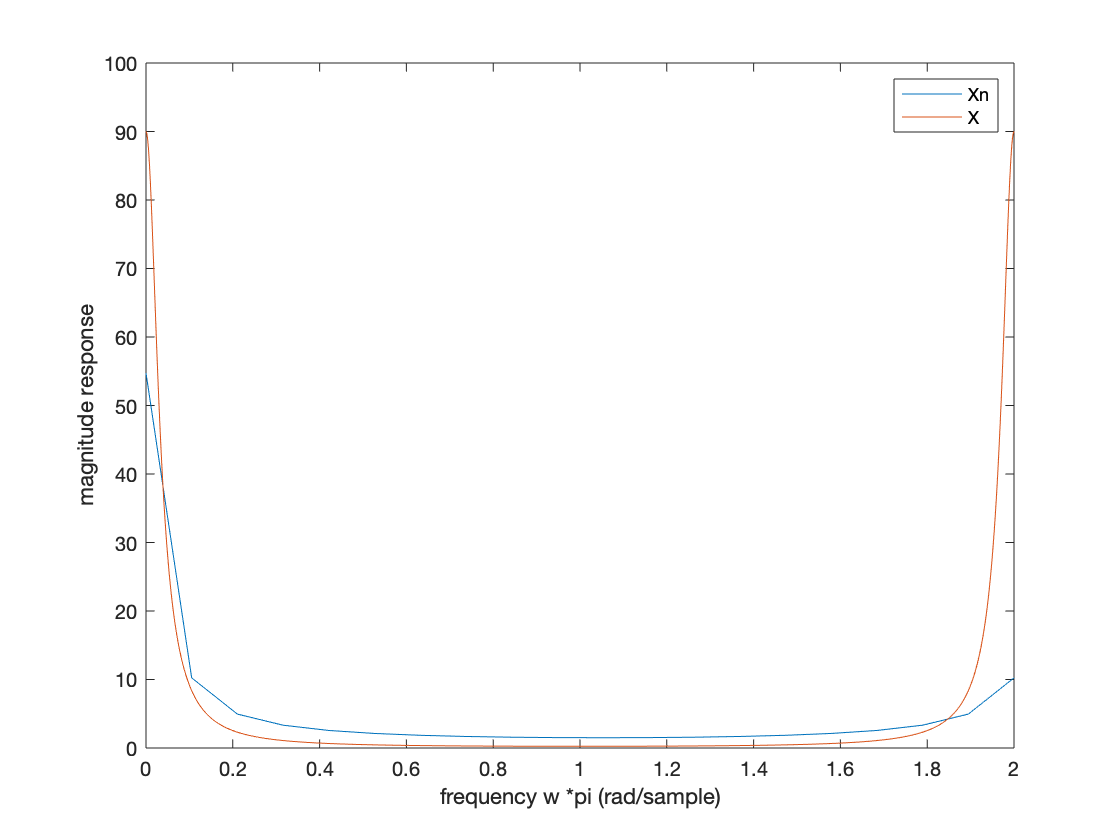

n=0:1:19;
x=n.*(0.9).^n;
Xn=fft(x);
om1=linspace(0,2*pi,20);

om2=linspace(0,2*pi,1000);
X=0.9*exp(-1i*om2)./(1-0.9*exp(-1i*om2)).^2;
figure
subplot(2,1,[1,2])
plot(om1/pi,abs(Xn),om2/pi,abs(X))
xlabel("frequency w *pi (rad/sample)")
ylabel("magnitude response")
legend("Xn","X")

當只取前20個點可看出畫出的magnitude與$\tilde{X} \left(e^{j\Omega } \right)$有差距，因為n>20的點沒納入，且在w接近2pi時，差距更大

(c)

N=50:

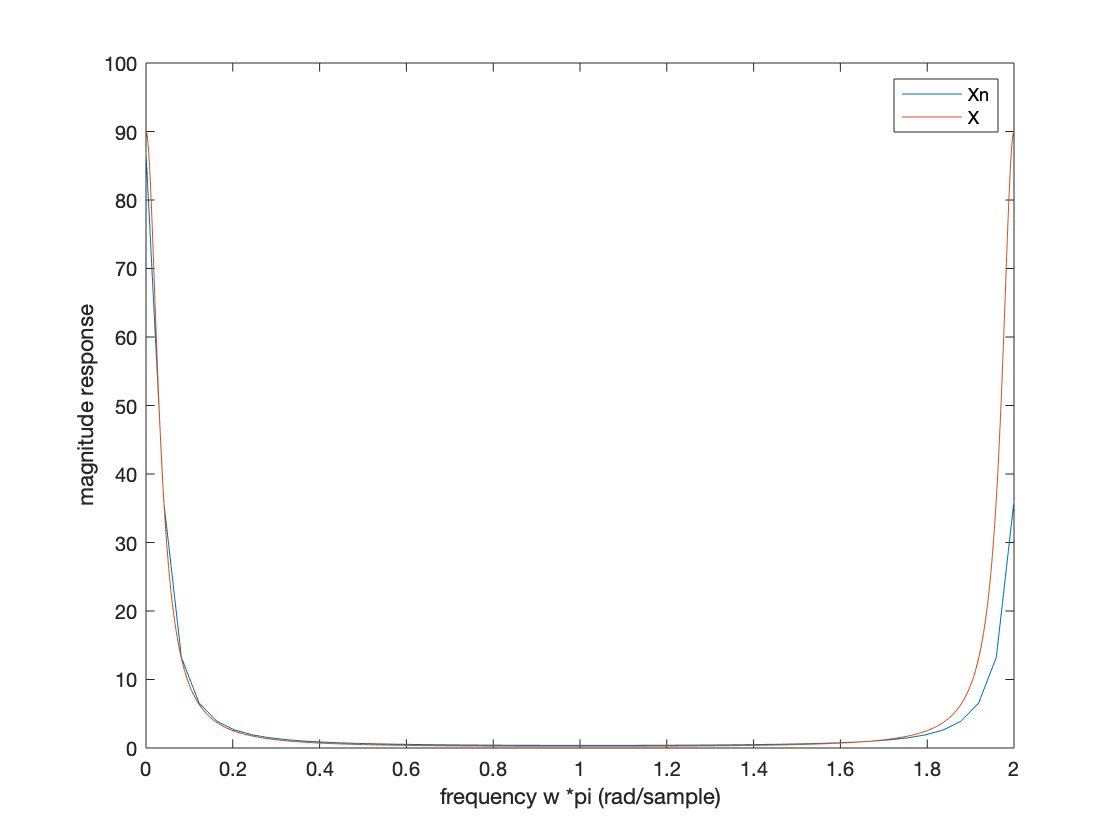

n=0:1:49;
x=n.*(0.9).^n;
Xn=fft(x);
om1=linspace(0,2*pi,50);

om2=linspace(0,2*pi,1000);
X=0.9*exp(-1i*om2)./(1-0.9*exp(-1i*om2)).^2;
figure
subplot(2,1,[1,2])
plot(om1/pi,abs(Xn),om2/pi,abs(X))
xlabel("frequency w *pi (rad/sample)")
ylabel("magnitude response")
legend("Xn","X")

當取前50個點可看出畫出的magnitude與$\tilde{X} \left(e^{j\Omega } \right)$有接近許多，但在w接近2pi時，還是有些許差異

(d)

N=100:

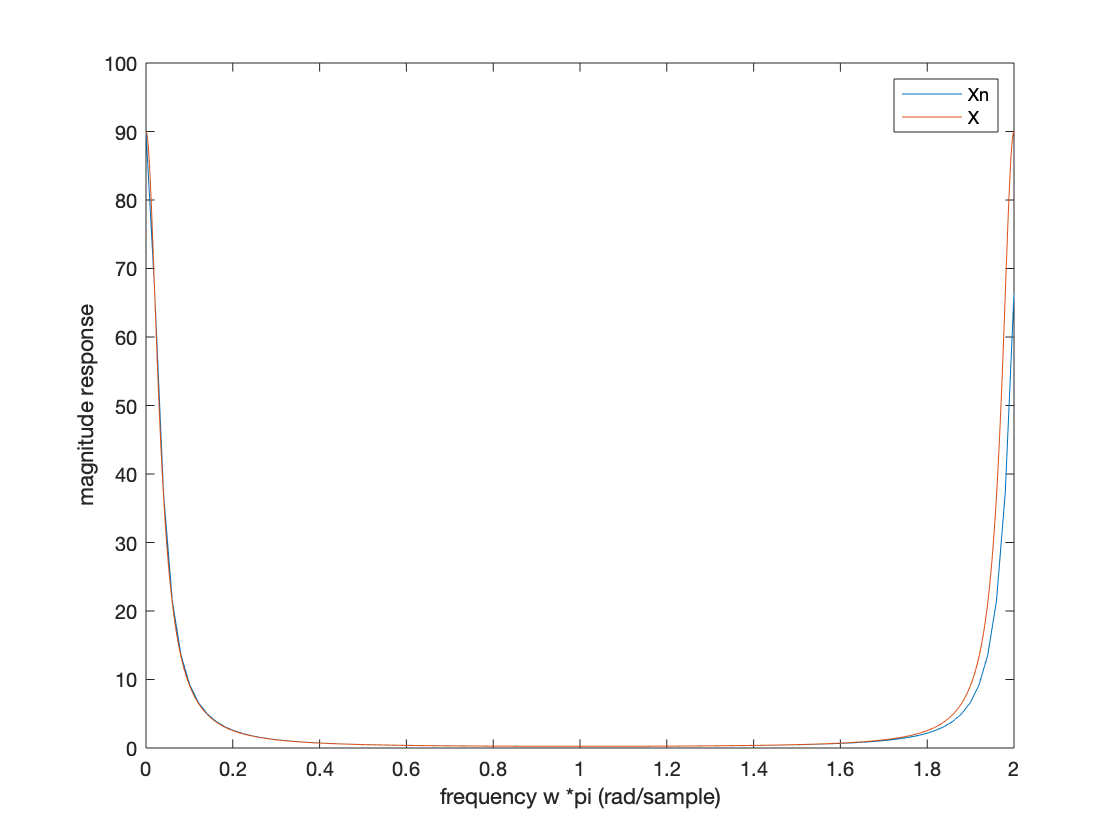

n=0:1:99;
x=n.*(0.9).^n;
Xn=fft(x);
om1=linspace(0,2*pi,100);

om2=linspace(0,2*pi,1000);
X=0.9*exp(-1i*om2)./(1-0.9*exp(-1i*om2)).^2;
figure
subplot(2,1,[1,2])
plot(om1/pi,abs(Xn),om2/pi,abs(X))
xlabel("frequency w *pi (rad/sample)")
ylabel("magnitude response")
legend("Xn","X")

當前100個點可看出畫出的magnitude與$\tilde{X} \left(e^{j\Omega } \right)$十分接近，只差在w接近2pi時，有點差異

當n=100，x=0.027，已經差不多涵蓋x[n]

2.

(a)


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =x_R \left\lbrack n\right\rbrack +{\textrm{jx}}_I \left\lbrack n\right\rbrack \;,\textrm{x1}\left\lbrack n\right\rbrack =x_R \left\lbrack n\right\rbrack \;,\;{\textrm{x2}\left\lbrack n\right\rbrack =x}_I \left\lbrack n\right\rbrack \;,\textrm{X1}\left\lbrack k\right\rbrack =X_R \left\lbrack k\right\rbrack =X^{\textrm{cce}} \left\lbrack k\right\rbrack \;,{\textrm{jX2}\left\lbrack k\right\rbrack =\textrm{jX}}_I \left\lbrack k\right\rbrack =X^{\textrm{cco}} \left\lbrack k\right\rbrack \\
X^{\textrm{cce}} \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack +X^* \left\lbrack {<-k>}_N \right\rbrack \right)\\
X\left\lbrack k\right\rbrack =X_R \left\lbrack k\right\rbrack +{\textrm{jX}}_I \left\lbrack k\right\rbrack \\
X^* \left\lbrack {<-k>}_N \right\rbrack =X_R \left\lbrack {<-k>}_N \right\rbrack +jX_I \left\lbrack {<-k>}_N \right\rbrack \\
X_R \left\lbrack {<-k>}_N \right\rbrack =X_R \left\lbrack k\right\rbrack \;,\;X_I \left\lbrack {<-k>}_N \right\rbrack =-X_I \left\lbrack k\right\rbrack \\
X^* \left\lbrack {<-k>}_N \right\rbrack =X_R \left\lbrack k\right\rbrack -jX_I \left\lbrack k\right\rbrack \\
\textrm{so},\;\;X^{\textrm{cce}} \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack +X^* \left\lbrack {<-k>}_N \right\rbrack \right)=\frac{1}{2}\left(X_R \left\lbrack k\right\rbrack +{\textrm{jX}}_I \left\lbrack k\right\rbrack +X_R \left\lbrack k\right\rbrack -jX_I \left\lbrack k\right\rbrack \right)=X_R \left\lbrack k\right\rbrack =\textrm{X1}\left\lbrack k\right\rbrack \\
X^{\textrm{cco}} \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack -X^* \left\lbrack {<-k>}_N \right\rbrack \right)=\frac{1}{2}\left(X_R \left\lbrack k\right\rbrack +{\textrm{jX}}_I \left\lbrack k\right\rbrack -\left(X_R \left\lbrack k\right\rbrack -jX_I \left\lbrack k\right\rbrack \right)\right)={\textrm{jX}}_I \left\lbrack k\right\rbrack =\textrm{jX2}\left\lbrack k\right\rbrack 
\end{array}$$


(b)

將x1設為實部x2設為虛部放入x中，

x[n] 經過DFT轉換$\Rightarrow X\left\lbrack k\right\rbrack$ , $x^* \left\lbrack n\right\rbrack$ 經過DFT轉換$\Rightarrow X^* \left\lbrack {<-k>}_N \right\rbrack$

透過公式


$$\begin{array}{l}
X^{\textrm{cce}} \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack +X^* \left\lbrack {<-k>}_N \right\rbrack \right)\;{=X}_R \left\lbrack k\right\rbrack \\
X^{\textrm{cco}} \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack -X^* \left\lbrack {<-k>}_N \right\rbrack \right)=\textrm{jX2}\left\lbrack k\right\rbrack 
\end{array}$$


可得X1和X2

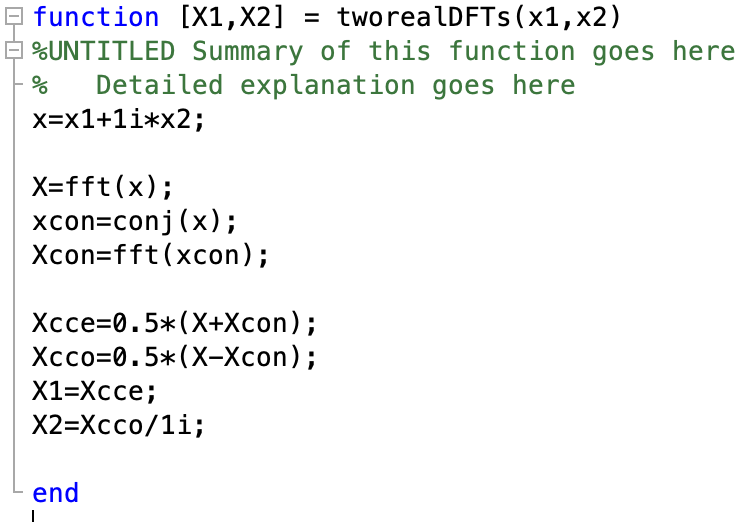

(c)

n=0:1:49;
x1=0.9.^n;
x2=1-0.8.^n;
[X1,X2]=tworealDFTs(x1,x2)

X1 =    9.9485 + 0.0000i   4.4039 - 4.6384i   1.9176 - 3.3459i   1.1903 - 2.4164i   0.9037 - 1.8541i   0.7646 - 1.4876i   0.6873 - 1.2311i   0.6401 - 1.0411i   0.6092 - 0.8941i   0.5880 - 0.7763i   0.5728 - 0.6792i   0.5616 - 0.5972i   0.5531 - 0.5266i   0.5466 - 0.4647i   0.5414 - 0.4096i   0.5374 - 0.3599i   0.5341 - 0.3144i   0.5315 - 0.2725i   0.5294 - 0.2333i   0.5277 - 0.1963i   0.5264 - 0.1611i   0.5253 - 0.1273i   0.5246 - 0.0946i   0.5240 - 0.0627i   0.5237 - 0.0312i   0.5236 + 0.0000i   0.5237 + 0.0312i   0.5240 + 0.0627i   0.5246 + 0.0946i   0.5253 + 0.1273i   0.5264 + 0.1611i   0.5277 + 0.1963i   0.5294 + 0.2333i   0.5315 + 0.2725i   0.5341 + 0.3144i   0.5374 + 0.3599i   0.5414 + 0.4096i   0.5466 + 0.4647i   0.5531 + 0.5266i   0.5616 + 0.5972i   0.5728 + 0.6792i   0.5880 + 0.7763i   0.6092 + 0.8941i   0.6401 + 1.0411i   0.6873 + 1.2311i   0.7646 + 1.4876i   0.9037 + 1.8541i   1.1903 + 2.4164i   1.9176 + 3.3459i   4.4039 + 4.6384i


X2 =   45.0001 + 0.0000i  -3.9209 + 1.9056i  -2.4940 + 2.2040i  -1.6814 + 1.9329i  -1.2566 + 1.6199i  -1.0209 + 1.3607i  -0.8800 + 1.1562i  -0.7903 + 0.9940i  -0.7300 + 0.8630i  -0.6877 + 0.7550i  -0.6571 + 0.6642i  -0.6343 + 0.5863i  -0.6169 + 0.5186i  -0.6034 + 0.4587i  -0.5928 + 0.4051i  -0.5843 + 0.3565i  -0.5775 + 0.3118i  -0.5721 + 0.2705i  -0.5677 + 0.2317i  -0.5641 + 0.1951i  -0.5613 + 0.1602i  -0.5592 + 0.1267i  -0.5575 + 0.0942i  -0.5564 + 0.0624i  -0.5558 + 0.0311i  -0.5555 + 0.0000i  -0.5558 - 0.0311i  -0.5564 - 0.0624i  -0.5575 - 0.0942i  -0.5592 - 0.1267i  -0.5613 - 0.1602i  -0.5641 - 0.1951i  -0.5677 - 0.2317i  -0.5721 - 0.2705i  -0.5775 - 0.3118i  -0.5843 - 0.3565i  -0.5928 - 0.4051i  -0.6034 - 0.4587i  -0.6169 - 0.5186i  -0.6343 - 0.5863i  -0.6571 - 0.6642i  -0.6877 - 0.7550i  -0.7300 - 0.8630i  -0.7903 - 0.9940i  -0.8800 - 1.1562i  -1.0209 - 1.3607i  -1.2566 - 1.6199i  -1.6814 - 1.9329i  -2.4940 - 2.2040i  -3.9209 - 1.9056i


X1_t=fft(x1)

X1_t =    9.9485 + 0.0000i   4.4039 - 4.6384i   1.9176 - 3.3459i   1.1903 - 2.4164i   0.9037 - 1.8541i   0.7646 - 1.4876i   0.6873 - 1.2311i   0.6401 - 1.0411i   0.6092 - 0.8941i   0.5880 - 0.7763i   0.5728 - 0.6792i   0.5616 - 0.5972i   0.5531 - 0.5266i   0.5466 - 0.4647i   0.5414 - 0.4096i   0.5374 - 0.3599i   0.5341 - 0.3144i   0.5315 - 0.2725i   0.5294 - 0.2333i   0.5277 - 0.1963i   0.5264 - 0.1611i   0.5253 - 0.1273i   0.5246 - 0.0946i   0.5240 - 0.0627i   0.5237 - 0.0312i   0.5236 + 0.0000i   0.5237 + 0.0312i   0.5240 + 0.0627i   0.5246 + 0.0946i   0.5253 + 0.1273i   0.5264 + 0.1611i   0.5277 + 0.1963i   0.5294 + 0.2333i   0.5315 + 0.2725i   0.5341 + 0.3144i   0.5374 + 0.3599i   0.5414 + 0.4096i   0.5466 + 0.4647i   0.5531 + 0.5266i   0.5616 + 0.5972i   0.5728 + 0.6792i   0.5880 + 0.7763i   0.6092 + 0.8941i   0.6401 + 1.0411i   0.6873 + 1.2311i   0.7646 + 1.4876i   0.9037 + 1.8541i   1.1903 + 2.4164i   1.9176 + 3.3459i   4.4039 + 4.6384i


X2_t=fft(x2)

X2_t =   45.0001 + 0.0000i  -3.9209 + 1.9056i  -2.4940 + 2.2040i  -1.6814 + 1.9329i  -1.2566 + 1.6199i  -1.0209 + 1.3607i  -0.8800 + 1.1562i  -0.7903 + 0.9940i  -0.7300 + 0.8630i  -0.6877 + 0.7550i  -0.6571 + 0.6642i  -0.6343 + 0.5863i  -0.6169 + 0.5186i  -0.6034 + 0.4587i  -0.5928 + 0.4051i  -0.5843 + 0.3565i  -0.5775 + 0.3118i  -0.5721 + 0.2705i  -0.5677 + 0.2317i  -0.5641 + 0.1951i  -0.5613 + 0.1602i  -0.5592 + 0.1267i  -0.5575 + 0.0942i  -0.5564 + 0.0624i  -0.5558 + 0.0311i  -0.5555 + 0.0000i  -0.5558 - 0.0311i  -0.5564 - 0.0624i  -0.5575 - 0.0942i  -0.5592 - 0.1267i  -0.5613 - 0.1602i  -0.5641 - 0.1951i  -0.5677 - 0.2317i  -0.5721 - 0.2705i  -0.5775 - 0.3118i  -0.5843 - 0.3565i  -0.5928 - 0.4051i  -0.6034 - 0.4587i  -0.6169 - 0.5186i  -0.6343 - 0.5863i  -0.6571 - 0.6642i  -0.6877 - 0.7550i  -0.7300 - 0.8630i  -0.7903 - 0.9940i  -0.8800 - 1.1562i  -1.0209 - 1.3607i  -1.2566 - 1.6199i  -1.6814 - 1.9329i  -2.4940 - 2.2040i  -3.9209 - 1.9056i


從 tworealDFTs function出來的X1和X2，與x1/x2直接經過DFTs轉換出的X1_t/X2_t做比較，

可看出數值相同，表示function正確

3.

(a)


$$\textrm{x1}\left\lbrack n\right\rbrack \bigcirc \textrm{x2}\left\lbrack n\right\rbrack =\sum_{m=0}^{N-1} \textrm{x1}\left\lbrack m\right\rbrack \textrm{x2}\left\lbrack {<n-m>}_N \right\rbrack$$



$$\begin{array}{l}
\textrm{x1}\left\lbrack n\right\rbrack =\left\lbrack 1\;2\;3\;4\;5\right\rbrack \;\;,\;\textrm{x2}=\left\lbrack 2-1\;1-1\;0\right\rbrack \\
y\left\lbrack 0\right\rbrack =\textrm{x1}\left\lbrack 0\right\rbrack \textrm{x2}\left\lbrack <0>\right\rbrack +\textrm{x1}\left\lbrack 1\right\rbrack \textrm{x2}\left\lbrack <-1>\right\rbrack +\textrm{x1}\left\lbrack 2\right\rbrack \textrm{x2}\left\lbrack <-2>\right\rbrack +\textrm{x1}\left\lbrack 3\right\rbrack \textrm{x2}\left\lbrack <-3>\right\rbrack +\textrm{x1}\left\lbrack 4\right\rbrack \textrm{x2}\left\lbrack <-4>\right\rbrack =2+0+-3+4-5=-2\\
y\left\lbrack 1\right\rbrack =\textrm{x1}\left\lbrack 0\right\rbrack \textrm{x2}\left\lbrack <1>\right\rbrack +\textrm{x1}\left\lbrack 1\right\rbrack \textrm{x2}\left\lbrack <0>\right\rbrack +\textrm{x1}\left\lbrack 2\right\rbrack \textrm{x2}\left\lbrack <-1>\right\rbrack +\textrm{x1}\left\lbrack 3\right\rbrack \textrm{x2}\left\lbrack <-2>\right\rbrack +\textrm{x1}\left\lbrack 4\right\rbrack \textrm{x2}\left\lbrack <-3>\right\rbrack =-1+4+-4+5=4\\
y\left\lbrack 2\right\rbrack =\textrm{x1}\left\lbrack 0\right\rbrack \textrm{x2}\left\lbrack <2>\right\rbrack +\textrm{x1}\left\lbrack 1\right\rbrack \textrm{x2}\left\lbrack <1>\right\rbrack +\textrm{x1}\left\lbrack 2\right\rbrack \textrm{x2}\left\lbrack <0>\right\rbrack +\textrm{x1}\left\lbrack 3\right\rbrack \textrm{x2}\left\lbrack <-1>\right\rbrack +\textrm{x1}\left\lbrack 4\right\rbrack \textrm{x2}\left\lbrack <-2>\right\rbrack =1+-2+6+-5=0\\
y\left\lbrack 3\right\rbrack =\textrm{x1}\left\lbrack 0\right\rbrack \textrm{x2}\left\lbrack <3>\right\rbrack +\textrm{x1}\left\lbrack 1\right\rbrack \textrm{x2}\left\lbrack <2>\right\rbrack +\textrm{x1}\left\lbrack 2\right\rbrack \textrm{x2}\left\lbrack <1>\right\rbrack +\textrm{x1}\left\lbrack 3\right\rbrack \textrm{x2}\left\lbrack <0>\right\rbrack +\textrm{x1}\left\lbrack 4\right\rbrack \textrm{x2}\left\lbrack <-1>\right\rbrack =-1+2-3+8=6\\
y\left\lbrack 4\right\rbrack =\textrm{x1}\left\lbrack 0\right\rbrack \textrm{x2}\left\lbrack <4>\right\rbrack +\textrm{x1}\left\lbrack 1\right\rbrack \textrm{x2}\left\lbrack <3>\right\rbrack +\textrm{x1}\left\lbrack 2\right\rbrack \textrm{x2}\left\lbrack <2>\right\rbrack +\textrm{x1}\left\lbrack 3\right\rbrack \textrm{x2}\left\lbrack <1>\right\rbrack +\textrm{x1}\left\lbrack 4\right\rbrack \textrm{x2}\left\lbrack <0>\right\rbrack =-2+3-4+10=7
\end{array}$$


(b)

x1=[1 2 3 4 5];
x1=x1';
x2=[2 -1 1 -1 0];
x2=x2';
y=circonv(x1,x2)

y =     -2
     4
     0
     6
     7


與上題比較後，兩者答案相同

c.

$\textrm{x1}\left\lbrack n\right\rbrack \bigcirc \textrm{x2}\left\lbrack n\right\rbrack \iff$Y[k]=X1[k]X2[k]

 求出Y[k]:

x1=[1 2 3 4 5];
x2=[2 -1 1 -1 0];
X1=fft(x1);
X2=fft(x2);
Y=X1.*X2

Y =   15.0000 + 0.0000i  -3.4549 + 6.3799i  -9.0451 - 3.9430i  -9.0451 + 3.9430i  -3.4549 - 6.3799i


再求y[n]：

y=ifft(Y)

y =    -2.0000    4.0000    0.0000    6.0000    7.0000


與(a)結果比較後兩者相同，驗證(a)結果正確

4.

(a)

y[n]=$\sum_{l=-\infty }^{\infty } \textrm{x3}\left\lbrack n+\textrm{lN}\right\rbrack$

先將x和h做convolution後，套用公式：

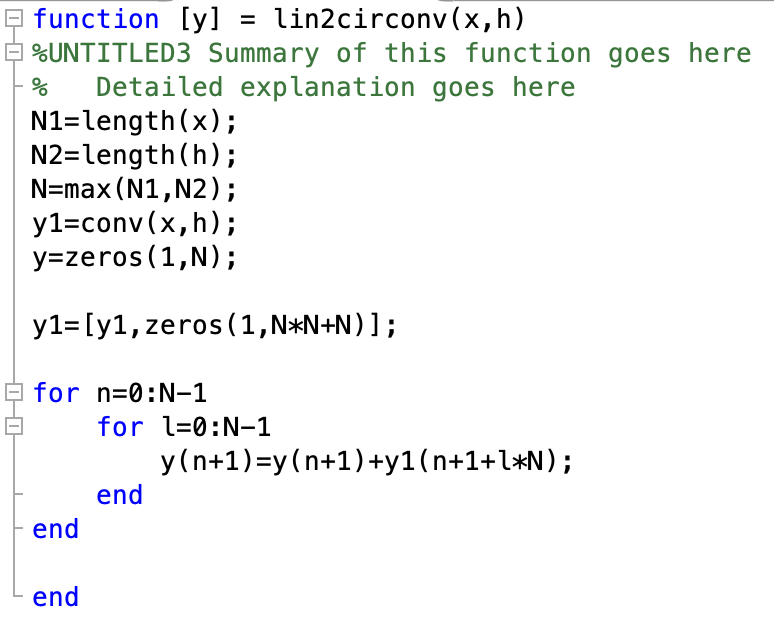

(b)

y1為使用lin2circonv的結果，與使用circonv的結果y2做比較：

x=[1 2 3 4];
h=[1 -1 1 -1];
y1=lin2circonv(x,h)

y1 =     -2     2    -2     2


x1=x';
x2=h';
y2=circonv(x1,x2)

y2 =     -2
     2
    -2
     2


兩者相同，驗正lin2circonv function正確

5.

(a)

h[m,n]=$\frac{1}{2\pi \times 16}e^{-\frac{m^2 +n^2 }{2\times 16}} \;,\textrm{for}\;\;\;-128\le m,n\le 127$

for m=-128:127
    for n=-128:127
        h(m+129,n+129)=(1/(2*pi*16))*exp(-((m^2)+(n^2))/(2*16));
    end
end
ffh=fft2(h);
%{
figure
imshow(log(abs(fftshift(ffh))+1))
title('Image A FFT2 Magnitude')
使用ishow畫圖時，會整個跑版，因此放上截圖
%}

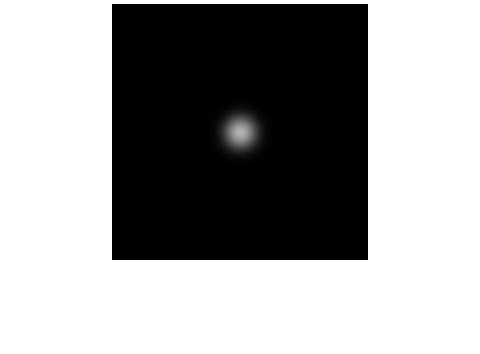

(b)

lena=imread('lena.jpg');
F=fft2(double(lena));
HPFS = ffh.*F;
HPF=(ifft2(HPFS)); 
%{
figure
imshow(uint8(abs(fftshift(HPF))));
使用ishow畫圖時，會整個跑版，因此放上截圖
%}

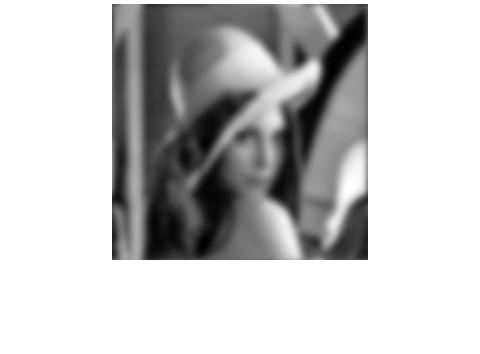

It's a Low-Pass Filter in DFT Domain, simply cut off all high frequency components that are

at a specified distance from the origin of the transform.

Low pass filtering removes high frequencies, then blurs image.

(c)

for m=-128:127
    for n=-128:127
        h2(m+129,n+129)=(1/(2*pi*1024))*exp(-(m^2+n^2)./(2*1024));
    end
end
ffh2=fft2(h2);
%{
figure
imshow(log(abs(fftshift(ffh1))+1))
title('Image A FFT2 Magnitude')
使用ishow畫圖時，會整個跑版，因此放上截圖
%}

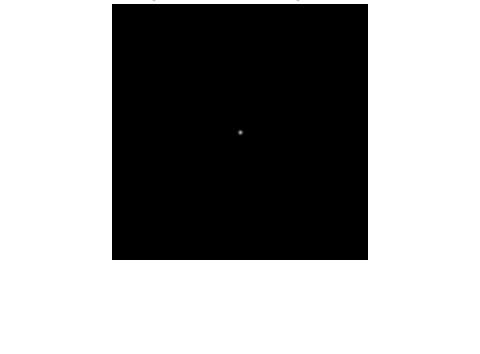

lena=imread('lena.jpg');
F=fft2(double(lena));
HPFS2 = ffh2.*F;
HPF2=(ifft2(HPFS2)); 
%{
figure
imshow(uint8(abs(fftshift(HPF2))));
使用ishow畫圖時，會整個跑版，因此放上截圖
%}

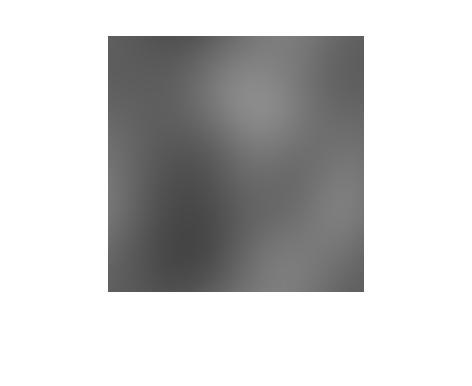

The kernel coefficients diminish with increasing distance from the kernel’s centre. Central pixels have a higher weighting than those on the periphery. Larger values of σ produce a wider peak in time domain, the narrower the filter in freqeuncy domain,  the more severe are the blurring.

(d)

for m=-128:127
    for n=-128:127
        h2(m+129,n+129)=(1/(2*pi*1024))*exp(-(m^2+n^2)./(2*1024));
    end
end

h2=padarray(h2,[256 256],0,'post');

lena=imread('lena.jpg');

lena=padarray(lena,[256 256],0,'post');

ffh2=fft2(h2);

F=fft2(double(lena));
HPFS2 = ffh2.*F;

HPF2=(ifft2(HPFS2)); 

%{
figure
imshow(uint8(abs((HPF2))))
使用ishow畫圖時，會整個跑版，因此放上截圖
%}

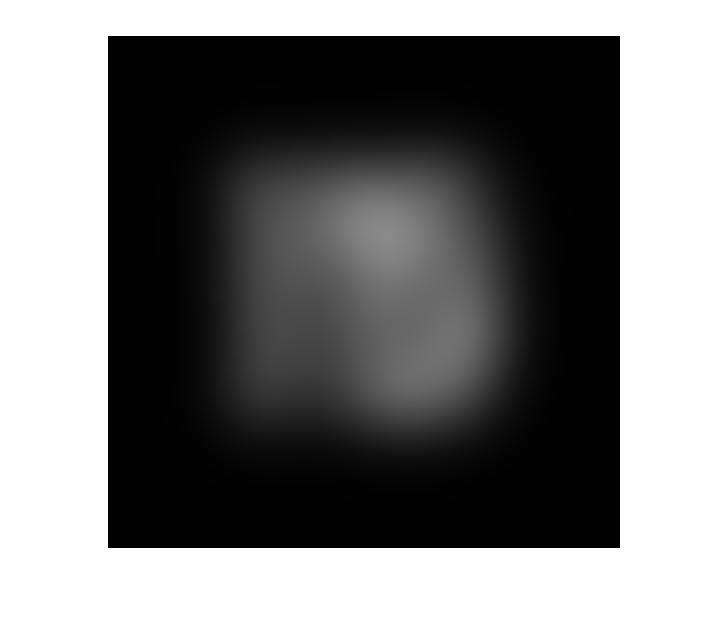

因爲DFT假定了輸入是無限和週期的，週期是N，我們需要對I和K進行zero padding

This means that the edge of the image will wrap over and combine with the other edge of the image. If pad with zeros, this is still happening, but the edges of the images are zero and therefore they are a lot less severe.

(e)

for m=-128:127
    for n=-128:127
        h(m+129,n+129)=(1/(2*pi*16))*exp(-((m^2)+(n^2))/(2*16));
    end
end
ffh=1-fft2(h);
%{
figure
imshow((abs(fftshift(ffh))))
%}

lena=imread('lena.jpg');
F=fft2(double(lena));
HPFS = (ffh).*F;
g=(ifft2(HPFS));


%{
figure
imshow(uint8(abs((g))));
使用ishow畫圖時，會整個跑版，因此放上截圖
%}

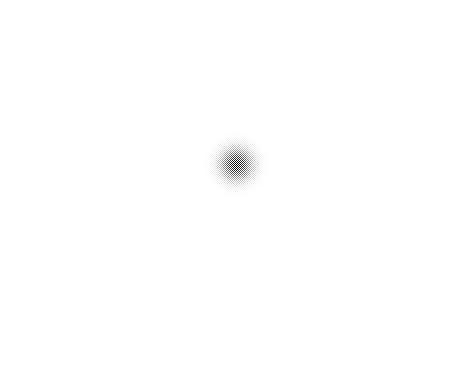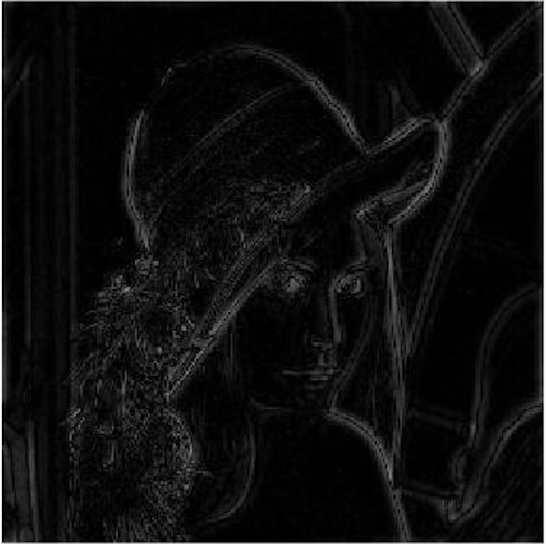

frequency response 變成1 − H[k, *l*]，此為high pass filter 

High pass filters are usually used for sharpening. 

只剩圖像變動劇烈的部分，通常是邊緣，也就是頻率高的地方會保留